Generate three sinusoidal signals x1(k), x2(k) and x3(k) with a fundamental frequency of 50, 100Hz and 150Hz, respectively, amplitude A = 1, sampling frequency equal to 1kHz and duration equal to 1 s.

Generate x4(k)=x1(k)+x2(k)+x3(k). 	

f1 = 50; %Hz
f2 =  100; %Hz
f3 =  150; %Hz
A = 1; % amplitude
f_s = 1000;
t = [0:1/1000:1];
d = 1 - 0; % duration


% function [x]=generate_sine(frequency,A,fs,duration)
x1 = generate_sine(f1, A, f_s, d);

x2 = generate_sine(f2, A, f_s, d);

x3 = generate_sine(f3, A, f_s, d);


x4 = x1 + x2 + x3;


# **Yule-Walker **

The Yule-Walker method estimates the autoregressive (AR) model parameters based on the autocorrelation sequence of the signal.

Matlab has a precompiled function implementing the Yule-Walker method. Its name is *aryule.m*. Check the help of the function to understand the outputs. 

**Apply the function on the signal x4(k) and identify the optimal model order**. 

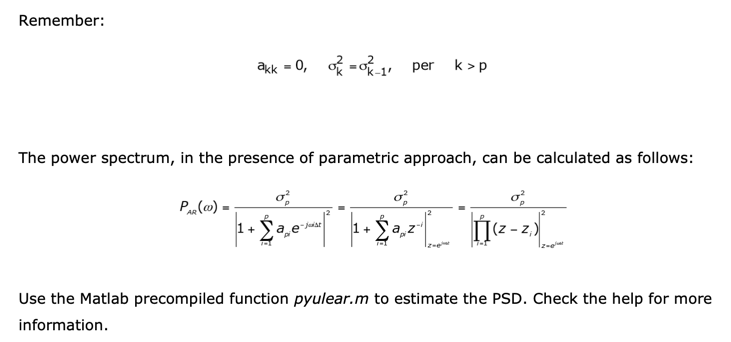

**Try to analyze the effect of the order on the PSD estimation. **





% Plotting error variance for Yule-Walker: 
% To determine the optimal model order, you can plot the error variance across different orders to find 
% where it stabilizes or reaches a plateau.
figure;

The optimal order is 20 with eyw = 0.007160


plot(2:max_order_yw, 10*log10(eyw_values(2:end)), 'b-', 'LineWidth', 2); % eyw_values for orders 2 to max
title('Error Variance - Yule-Walker');
xlabel('Model Order');
ylabel('Error Variance (dB)');
grid on;

% PSD estimation using optimal Yule-Walker order
optimal_order_yw = find(eyw_values == min(eyw_values), 1, 'last'); % Ensure it captures the last minimal variance
[pxx_yw, f] = pyulear(x4, optimal_order_yw, [], f_s);

figure;
plot(f, 10*log10(pxx_yw), 'b', 'LineWidth', 2);
title('Power Spectral Density using Yule-Walker');
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');
grid on;


%{
      [a,e,rc] = aryule(x,p)
 aryule - Autoregressive all-pole model parameters — Yule-Walker method

The optimal order is 20 with eyv = 0.007153


    This MATLAB function returns the normalized autoregressive (AR)

The optimal order is 7 with eb = 0.000000


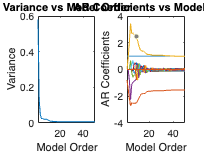

    parameters corresponding to a model of order p for the input array x.

    Input Arguments
      x - Input array / vector | matrix
      p - Model order / positive integer scalar

    Output Arguments
      a - Normalized autoregressive parameters / row vector | matrix
      e - White noise input variance / scalar | row vector
      rc - Reflection coefficients / vector | matrix
%}

% Yule-Walker method

% optimal order:autoregressive coeff circa zero varianza al passo kk è
% uguale a quella del passo kk-1

optimal_order = 15; % Initial guess for optimal model order
[a, e] = aryule(x4, optimal_order); % Compute AR coefficients and error variance for order 15

% Verifying that the variance remains unaltered for a different order
[a1, e1] = aryule(x4, optimal_order - 1); % AR coefficients and error variance for order 14

% Determine the optimal model order
max_order = 50; % Maximum order to test
e_values = zeros(1, max_order); % Initialize array to store error variances
a_coeffs = zeros(max_order, max_order); % Initialize array to store AR coefficients

% Loop through each order from 1 to max_order
for p = 1:max_order
    [a_coeffs(p, 1:p+1), e_values(p)] = aryule(x4, p); % Compute AR coefficients and error variance for order p
end

% Plot the variance and AR coefficients for each model order
figure;
subplot(1, 2, 1);
plot(1:max_order, e_values); % Plot error variance vs. model order
title('Variance vs Model Order');
xlabel('Model Order');
ylabel('Variance');
xlim([1 max_order]);

subplot(1, 2, 2);
plot(1:max_order, a_coeffs); % Plot AR coefficients vs. model order
title('AR Coefficients vs Model Order');
xlabel('Model Order');
ylabel('AR Coefficients');
xlim([1 max_order]);

% Power Spectral Density estimation using pyulear
order = optimal_order; % Choose an appropriate order based on previous analysis
[pxx, f] = pyulear(x4, order, [], f_s); % Estimate the PSD using Yule-Walker AR method

% Plot the Power Spectral Density

figure;
plot(f, 10*log10(pxx)); % Convert power to dB/Hz
title('Power Spectral Density using Yule-Walker AR method');
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');
grid on;

The problem is that the order of the model is not known in advance. 

In real signals to understand the optimal order we look at the behavior of the reflection coefficients (they should go to zero) and at the variance. Ideally also this last parameter should go to zero but in reality we stop when it reaches a plateau or the knee of the function. 					

Moreover usually for the matlab implementation it is prefereable to use an odd order 

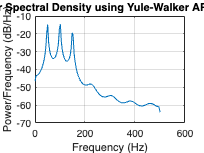

%% YULE-WALKER

[a,e]= aryule(x4,15);
[a1,e1]= aryule(x4,14);% verifico che la varianza rimanga inalterata

p=1;

n=50;%max value of model order
for i=1:n
    [a,e(i)] = aryule(x4,p);
    p=p+1;
end

subplot(1,2,1);
plot(e);
title('variance')
xlabel('model order')
xlim([1 n])
subplot(1,2,2);
plot(a);
title('AR coefficient')
xlabel('model order')
xlim([1 n])

%% PSD
[pxx,f] = pyulear(x4,15,length(x4),fs);
plot(f,pxx);

for i=5:50
    [Pxx,f]=pyulear(x4,i,length(x4),fs);
    plot(f,10*log10(Pxx));%with the log I consider the variance
    %plot(f,(Pxx));%i can see the frequency resolution
    legend(num2str(i));
    
    pause(0.25)
end
figure();



%% BURG'S METHOD

[a,e]=arburg(x4,order);

Invalid expression. Check for missing multiplication operator, missing or unbalanced delimiters, or other syntax error. To construct matrices, use brackets instead of parentheses.


[pxx,f]=pburg(x4,order,f number of samples ,fs);

plot(f,10*log10(pxx));

%DEMO
n2=50;
%the variance decrease and frequency resolution is the same of the YW
for i=1:n2
    [a,e(i)]=arburg(x4,i);
    [Pxx,f]=pburg(x4,i,length(x4),fs);
    plot(f,10*log10(Pxx));
    %plot(f,Pxx);%vede 1 solo picco perchè ho un problema di visualizzazione
    legend(num2str(i));
    
    pause(0.25)
end


% Parameters
threshold_burg = 0.00001;  % Variation threshold of eb
max_order_burg = 100;      % Max order to consider

% Initialization of previous eb to compare
[aburg_prev, prev_eb] = arburg(x4, 1);

for order_burg = 2:max_order_burg
    % Calculate the coefficient and the variance of AR using Burg's method
    [aburg, eb] = arburg(x4, order_burg);

    % Monitor the variance of eb
    if abs(prev_eb - eb) < threshold_burg
        fprintf('The optimal order is %d with eb = %.6f\n', order_burg, eb);
        break;
    end

    % Update the previous eb
    prev_eb = eb;

    % If it gets up to the max order without satisfying the conditions
    if order_burg == max_order_burg
        fprintf('Reached the maximum order (%d) with eb = %.6f\n', max_order_burg, eb);
    end
end
